# Seminar 1

## PROBLEM 13

File SM22_Seminar_1_13.xlsx contains data from the marks obtained by students in 2 out of the 5 labs of Statistical Models in the course 2019-2020 (first 2 columns in each row). The last column contains a binary indicator of whether the corresponding student passed the course (1) or not (0). Therefore, we can consider that we have 2 random samples of 2 dimensions  each (students who passed the course and those who did not pass). For each of these two random samples, and assuming that they follow a multivariate normal distribution:

% Importing table

filename = 'semi1/SM22_Seminar_1_13.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

### a) Calculate and draw 95% confidence regions for the population means. Recall to consider separately the two populations of students (who passed and who did not pass) and therefore you will construct two separate confidence regions.

% passPopulationIdx = raw(:,3) == 1
% raw(:,3) == 1 equivalent to logical(raw(:,3))
% () return tables, {} return arrays
alpha = 0.05;

passPopulation = raw{raw{:,3} == 1,[1, 2]};
noPassPopulation = raw{raw{:,3} == 0,[1, 2]};

smeanPass = smean(passPopulation);
disp(['Pass Population Sample Mean: [' num2str(smeanPass(:).') ']']);

Pass Population Sample Mean: [7.625      8.4911]



smeanNoPass = smean(noPassPopulation);
disp(['No-Pass Population Sample Mean: [' num2str(smeanNoPass(:).') ']']);

No-Pass Population Sample Mean: [6.1429      6.7679]



sstdPass = sstd(passPopulation);
disp('Pass Population Standard Error:');

Pass Population Standard Error:


disp(sstdPass);

    2.2153    1.4549
    1.4549    1.5532




sstdNoPass = sstd(noPassPopulation);
disp('No-Pass Population Standard Error:');

No-Pass Population Standard Error:


disp(sstdNoPass);

    4.7184    1.5598
    1.5598    2.8506




% of the form px2
ciPass = confInterval(passPopulation, alpha);
disp('Pass Population CI:');

Pass Population CI:


disp(ciPass);

    6.8810    8.3690
    7.8681    9.1141




ciNoPass = confInterval(noPassPopulation, alpha);
disp('No-Pass Population CI:');

No-Pass Population CI:


disp(ciNoPass);

    4.4585    7.8272
    5.4586    8.0771




disp('Plotting regions for Pass Population:');

Plotting regions for Pass Population:


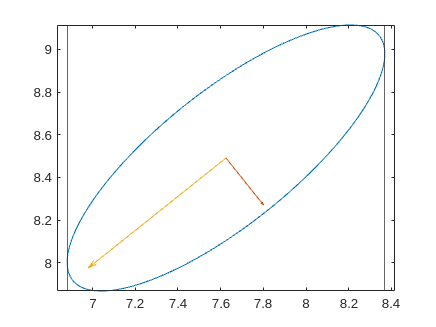

cla;
drawCI(passPopulation, alpha);


disp('Plotting regions for No-Pass Population:');

Plotting regions for No-Pass Population:


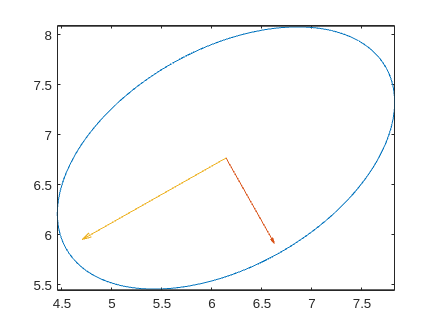

cla;
drawCI(noPassPopulation, alpha);


function m = smean(pop)
    m = sum(pop, 1) / length(pop);
end

function s = sstd(pop)
    s = (pop-smean(pop))'*(pop-smean(pop)) / (length(pop)-1);
end

function ci = confInterval(pop, alpha)
    n = size(pop, 1);
    p = size(pop, 2);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));
    s_diag = diag(sstd(pop)); % vector containing the diagonal only
    x_bar = smean(pop);
    ci = [x_bar' - c*sqrt(s_diag/n), x_bar' + c*sqrt(s_diag/n)];
end

function axis = getEllipsisAxis(pop, alpha)
    n = size(pop, 1);
    p = size(pop, 2);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));

    [eVec, eVal] = eig(sstd(pop));
    eVal = diag(eVal);

    axis = c * sqrt(eVal/n)' .* eVec;
end

function drawCI(pop, alpha)
    % First we draw the ellipsis 
    center = smean(pop);
    ellipsis_axis = getEllipsisAxis(pop, alpha);

    t = -pi:0.01:pi;
    circle = [cos(t)', sin(t)'];
    ellipsis = center + circle * ellipsis_axis';

    plot(ellipsis(:,1), ellipsis(:,2));
    hold on;

    % Then we plot the axis of the ellipsis
    quiver(center(1), center(2), ellipsis_axis(1,1), ellipsis_axis(2,1));
    hold on;
    quiver(center(1), center(2), ellipsis_axis(1,2), ellipsis_axis(2,2));
    hold off;

    % Now we draw the confidence intervals (Hotelling's)
    ci = confInterval(pop, alpha);
    xline(ci(1,1));
    xline(ci(1,2));
    yline(ci(2,1));
    yline(ci(2,2));

    axis equal;
end

### b) Calculate 95% confidence intervals for the marks of the two groups of students for each lab.

fullPopulation = raw{:, [1,2]};

smeanFull = smean(fullPopulation);
disp(['Full Population Sample Mean: [' num2str(smeanFull(:).') ']']);

Full Population Sample Mean: [7.131      7.9167]



sstdFull = sstd(fullPopulation);
disp('Full Population Standard Error:');

Full Population Standard Error:


disp(sstdFull);

    3.4550    2.0340
    2.0340    2.6026




ciFull = confInterval(fullPopulation, alpha);
disp('Full Population CI:');

Full Population CI:


disp(ciFull);

    6.3927    7.8692
    7.2759    8.5574



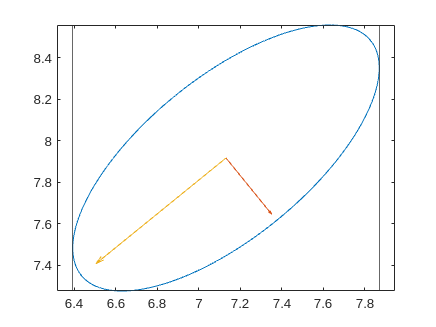


cla;
drawCI(fullPopulation, alpha);

### c) Based on your results in (a) and (b), is it possible to extract any conclusion regarding the average marks of these two labs between students who passed or failed the subject?

Yes. By analyzing both groups separately we can see that they have very different grade distributions. If we did not analyze them separately, we would arrive to the conclusions of section b. We can see the differences in the same plot below:

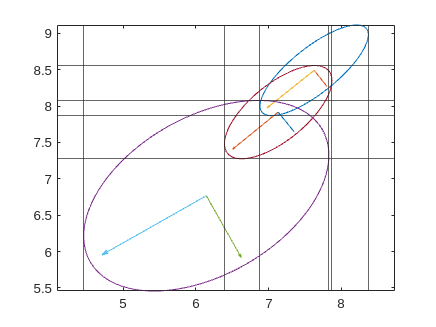

cla;
drawCI(passPopulation, alpha);
hold on;
drawCI(noPassPopulation, alpha);
hold on;
drawCI(fullPopulation, alpha);